This is a script for generating the final videos of the octopus arm morphology tracking script process. 

It takes as input the workspace variables generated by eb_arm_tracking_step3.m

This final step was necessary to overcome certain limitations. 

## load in the workspace variables

workspace_vars = sprintf('workspace_vars_%s.mat', date);
load(workspace_vars);

## now that we have all that, we can create the last video:

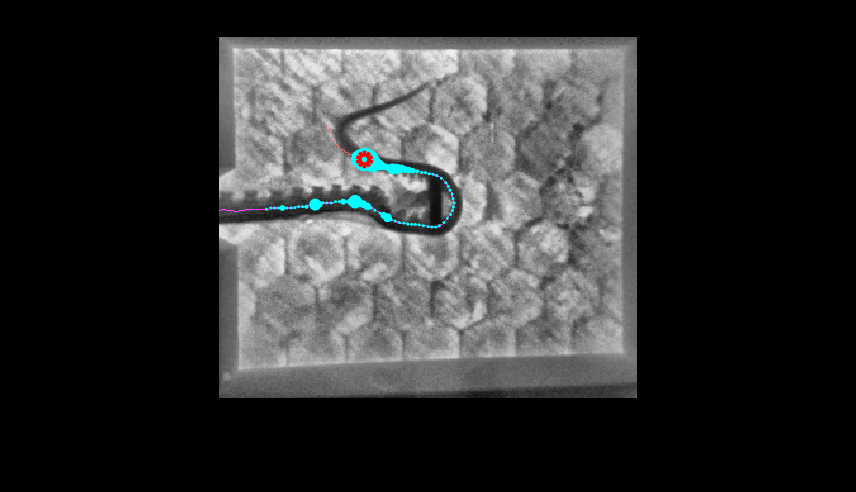

imshow(FRM(:,:,:,end-2))
hold on

for b1 = 3:size(TH,1)
    plot(SEG(b1, 2, end-2), SEG(b1, 1, end-2),'c.','markersize', xp(b1).*40 + 1)
end
axis([160 490 60 345])
plot(SEG(ind,2,end-2),SEG(ind,1,end-2),'ro','linewidth',3)
drawnow
pause(0.05)
axis off
set(gcf,'color','k')

clear m 
cmap = colormap('jet');

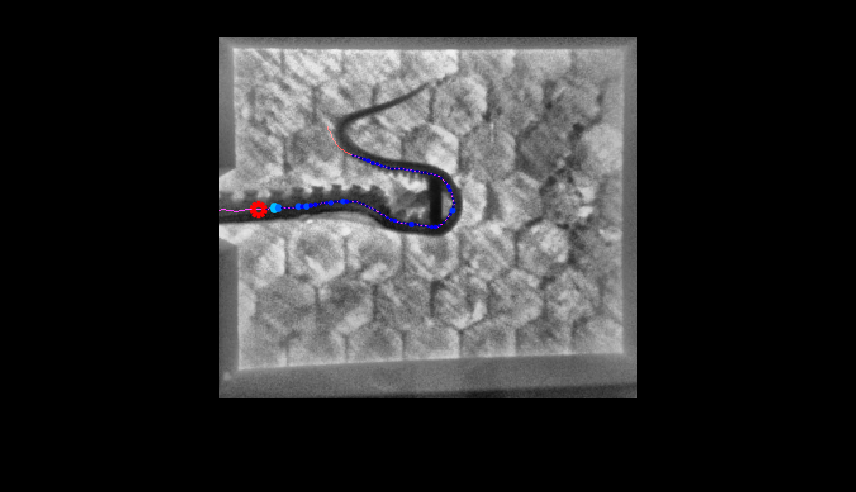

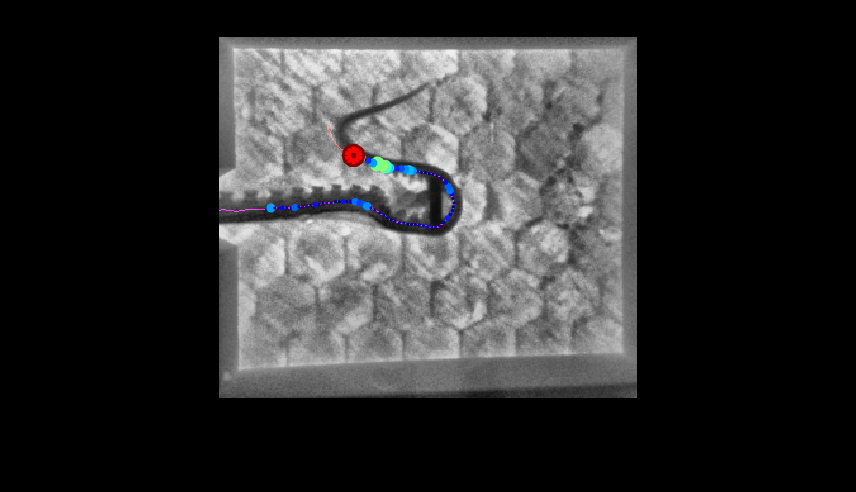

figure,
ed1 = 1;
vid_sv = 1;
for b = 1:size(xc1,2)
    ind = b;
    xp = xc1(:,ind);
    xp(xp<0) = 0;
    xpc = round(xp.*63)+1;
    PC = cmap(xpc,:);
    hold off
    if ed1 == 1
        imshow(FRM(:,:,:,end-2))
    else
        imshow(FRM(:,:,:,1))
    end
    
    hold on
    for b1 = 3:size(TH,1)
        if ed1 == 1
            plot(SEG(b1,2,end-2),SEG(b1,1,end-2),'c.','markersize', ...
                xp(b1).*40 + 1, 'color', PC(b1,:))
        else
            plot(SEG(b1,2,1),SEG(b1,1,1),'c.','markersize',... 
                xp(b1).*40 + 1, 'color', PC(b1, :))
        end
    end
    
    axis([160 490 60 345])
    if ed1 == 1
        plot(SEG(ind, 2, end-2), SEG(ind, 1, end-2), 'ro','linewidth', 3)
    else
        plot(SEG(ind, 2, 1), SEG(ind, 1, 1),'ro', 'linewidth', 3)
    end
    drawnow
    pause(0.1)
    axis off
    set(gcf,'color','k')
    if vid_sv == 1
        m(b) = getframe;
    end
end

VidObj = VideoWriter(sprintf('%sArm_correlation_30fps_color.avi', destdirname));
VidObj.FrameRate = 30;
open(VidObj);
for b = 1:size(m,2)
    writeVideo(VidObj, m(b).cdata);
end
close(VidObj);
clear VidObj